Ewell lab, 2025, gt

Pipeline to reproduce figures in the section of *Context-dependent and context-independent memory tasks to test the impact of context relevance on hippocampal remapping.* The analysis relies on two datasets:

1) Behavior data to show mice can lear the discrimination task (BehaviorData.mat)

2) Lesion data to show that the hippocampus is necessary to solve the task (LesionData.mat)

The notebook uses the struct generated in the CreateStructBehavior.m and CreateStructLesion.m scripts. The struct contains position data, event file for each day for each mouse in discrimination and generalization (sometimes referred to as grouping). Note: the implanted field refers to optic fiber and GRIN lens implant. Additionally, it reads the performance of the miniscope mice (it's already calculated from the event files).

Change the path where the data is located here:

main_path = "C:\Users\ewell\Desktop\TestCodeGitHub\";
warning('off') %turn off warnings
addpath(strcat(main_path, "Discrimination 2025 CodeBase\Behavior_codes"),strcat(main_path, "Discrimination 2025 CodeBase\Behavior_codes\violinPlot"))


Load Behavior struct and calculate performance for these set of mice. This script can be found in the BehaviorLearning.m script as well. Overall performance, ctxt A/C and ctxt B/D performances are stored in Performance_d and Performance_g variables.

cd(strcat(main_path, "\Discrimination 2025 data\Behavior\"))
if ~exist("behavior_struct", "var")
    load BehaviorData
    behavior_struct.details.GPassed(5) =behavior_struct.details.GPassed(5)-1; % count the first day of > 70% for M99 because 2nd had behavior problems (cold room)
end

[N_days_d, N_mice] = size(behavior_struct.D_events);
Performance_d = nan(N_days_d,N_mice+8, 3); % to store performance  - total, ctxt A & ctxt B

%% get Performance for discrimination
for m = 1:N_mice
    disp(behavior_struct.details.Mouse(m))
    for d = 1:N_days_d
    event = behavior_struct.D_events{d,m};
    if isempty(event)
        break;
    end
    [TrialStart, TrialStop, ZoneTriggered, context] = ParseTrials(event);
    [Correct, Incorrect, Timeout, port, time, TrainingTrials, all_outcome] = GetTrialOutcome(event,TrialStart,TrialStop,ZoneTriggered);
    TrialType  = ones(length(all_outcome),1);
    if ~isempty(TrainingTrials)
        TrialType([1; TrainingTrials(:,1)]) = 0; %1st trial is training when training trials are included in the session
    end
        Performance_d(d,m,:) = GetPerformance(TrialType, context, all_outcome);
    end

end

M95
M96
M97
M98
M99
M100
M114
M115
M116
M117



%% get performance for generalization
[N_days_g, N_mice] = size(behavior_struct.G_events);
Performance_g = nan(N_days_g,N_mice+8, 3); % to store performance  - total, ctxt A & ctxt B

for m = 1:N_mice
    disp(behavior_struct.details.Mouse(m))
    for d = 1:N_days_g
    event = behavior_struct.G_events{d,m};
    if isempty(event)
        break;
    end
    [TrialStart, TrialStop, ZoneTriggered, context] = ParseTrials(event);
    [Correct, Incorrect, Timeout, port, time, TrainingTrials, all_outcome] = GetTrialOutcome(event,TrialStart,TrialStop,ZoneTriggered);
    TrialType  = ones(length(all_outcome),1);
    if ~isempty(TrainingTrials)
        TrialType([1; TrainingTrials(:,1)]) = 0; %1st trial is training when training trials are included in the session
    end
        Performance_g(d,m,:) = GetPerformance(TrialType, context, all_outcome);
    end

end

M95
M96
M97
M98
M99
M100
M114
M115
M116
M117



% read perfomance of the miniscope mice
disp("Miniscope mice:")

Miniscope mice:


folders = strings(5,2);
folders(:,1) = ["M119"  "M120" "M292" "M319" "M210"];
folders(:,2) = ["M231" "M314"  "M316" "M318" ""];

nMice = [5 4];
MiniscopeSex = ["f" "f" "f" "m" "m" "m", "f" "m" "m"];
counter = 1;
for r = 1:2
    for f = 1:nMice(r)
        disp(folders(f,r))
        load(strcat(main_path,"\Discrimination 2025 data\Behavior\Miniscope mice performance\" , folders(f,r), "\Performance_d.mat"))
        [days, ~,~]  = size(Performance);
        Performance_d(1:days,counter+10,:) = Performance;
        clear Performance
        
        if exist(strcat(main_path,"\Discrimination 2025 data\Behavior\Miniscope mice performance\", folders(f,r), "\Performance_g.mat"), "file") 
            load(strcat(main_path,"\Discrimination 2025 data\Behavior\Miniscope mice performance\", folders(f,r), "\Performance_g.mat"))
            [days, ~,~]  = size(Performance);
            Performance_g(1:days,counter+10,:) = Performance;
            clear Performance
        else
            Performance_g(1:days,counter+10,:) = nan(days,3);
        end
        counter = counter +1;
    end
end

M119
M120
M292
M319
M210
M231
M314
M316
M318


Now group males and females and get which day they reach criteria - with stats

males = [find(behavior_struct.details.Sex == "m"); find(MiniscopeSex == "m")'+10];
females = [find(behavior_struct.details.Sex == "f"); find(MiniscopeSex == "f")'+10];

%% get when they reached 70%
Main_Perform_D = Performance_d(:,:,1);
Main_Perform_G = Performance_g(:,:,1);

Discrimination_70 = nan(19,2);% number of mice manually set (19)
Grouping_70 = nan(19,2);

for i = 1:19 
   idx = find(Main_Perform_D(:,i) >= 70);
   Discrimination_70(i,1) = idx(1);
   Discrimination_70(i,2) = Main_Perform_D(idx(1),i);
   idx = find(Main_Perform_G(:,i) >= 70);
   if ~isempty(idx)
        Grouping_70(i,1) = idx(1);
        Grouping_70(i,2) = Main_Perform_G(idx(1),i);
   end
end

Y_D = nan(10,2);
Y_G = nan(10,2);

Y_D(1:length(females),1) = Discrimination_70(females,1);
Y_D(1:length(males),2) = Discrimination_70(males,1);

Y_G(1:length(females),1) = Grouping_70(females,1);
Y_G(1:length(males),2) = Grouping_70(males,1);

% statistics
[~,p_D, ci_D, stats_D] = ttest2(Y_D(:,1), Y_D(:,2)); % female vs male discrimination
[~,p_G,ci_G,stats_G] = ttest2(Y_G(:,1), Y_G(:,2)); % female vs male generalization
p_D

p_D = 0.4850

p_G

p_G = 0.1511

## Figure 1 Panel D

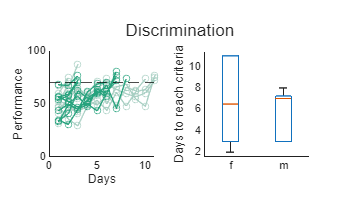

figure
t= tiledlayout(1,2);
title(t, "Discrimination")
nexttile;
hold on
box off
axis square
for i = 1:length(females)
    plot(Main_Perform_D(1:Discrimination_70(females(i),1),females(i)),"o-", "MarkerSize",5, "Color","#a8cfc3")
end

for i = 1:length(males)
    plot(Main_Perform_D(1:Discrimination_70(males(i),1),males(i)),"o-", "MarkerSize",5, "Color","#27a37d")
end
yline(70, 'k--')
ylim([0 100])
xlim([0 11])
xlabel("Days")
ylabel("Performance")

nexttile;
boxplot(Y_D)
axis square
box off
xticklabels({"f", "m"})
ylabel("Days to reach criteria")

## Figure 1 Panel E

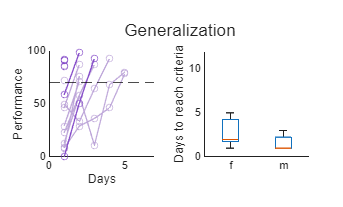

figure
t= tiledlayout(1,2);
title(t, "Generalization")
nexttile;
hold on
box off
axis square
for i = 1:length(females)
    if ~isnan(Grouping_70(females(i),1))
        plot(Main_Perform_G(1:Grouping_70(females(i),1),females(i)),"o-", "MarkerSize",5, "Color","#bea7d9")
    end
end

for i = 1:length(males)
    if ~isnan(Grouping_70(males(i),1))
        plot(Main_Perform_G(1:Grouping_70(males(i),1),males(i)),"o-", "MarkerSize",5, "Color","#854bc9")
    end
end
xlim([0 7])
ylim([0 100])
xlabel("Days")
ylabel("Performance")
yline(70, 'k--')

nexttile;
boxplot(Y_G)
ylim([0 12])
axis square
box off
xticklabels({"f", "m"})
ylabel("Days to reach criteria")

The second part of the analysis read the LesionData.struct to calculate performance before and after lesion. Codes can be found in the LesionPerformance.m as well. Ignore messages about short event flags. Make sure to add Codes/violinPlot to your path.

disp("--------- Lesion analysis ---------")

--------- Lesion analysis ---------


load LesionData

ctrl = find(lesion_struct.details.Group == "c");
lesion = find(lesion_struct.details.Group == "l");
starting_day = lesion_struct.details.LesionD1-1;

%calculate performance for these days
[~, N_mice] = size(lesion_struct.events);
Performance = nan(5,N_mice,3);

for m = 1:N_mice
    disp(lesion_struct.details.Mouse(m))
    %for d = starting_day(m):starting_day(m)+4
    for d = starting_day(m):starting_day(m)+4
    event = lesion_struct.events{d,m};
    [TrialStart, TrialStop, ZoneTriggered, context] = ParseTrials(event);
    [Correct, Incorrect, Timeout, port, time, TrainingTrials, all_outcome] = GetTrialOutcome(event,TrialStart,TrialStop,ZoneTriggered);
    TrialType  = ones(length(all_outcome),1);
    if ~isempty(TrainingTrials)
        TrialType([1; TrainingTrials(:,1)]) = 0; %1st trial is training when training trials are included in the session
    end
        %Performance(d-starting_day(m)+1,m,:) = GetPerformance(TrialType, context, all_outcome);
        Performance(d-starting_day(m)+1,m,:) = GetPerformance(TrialType, context, all_outcome);
    end
end

M94
M113
M118


Too short event flag in line 1466. Skipped for now but please fix it manually in the EventFile.
Too short event flag in line 708. Skipped for now but please fix it manually in the EventFile.


M122


Too short event flag in line 991. Skipped for now but please fix it manually in the EventFile.


M151
M152
M154


Too short event flag in line 1212. Skipped for now but please fix it manually in the EventFile.


M155


Too short event flag in line 1396. Skipped for now but please fix it manually in the EventFile.
Too short event flag in line 1648. Skipped for now but please fix it manually in the EventFile.


M179
M180


Too short event flag in line 744. Skipped for now but please fix it manually in the EventFile.
Too short event flag in line 3847. Skipped for now but please fix it manually in the EventFile.
Too short event flag in line 4468. Skipped for now but please fix it manually in the EventFile.
Too short event flag in line 3394. Skipped for now but please fix it manually in the EventFile.
Too short event flag in line 3990. Skipped for now but please fix it manually in the EventFile.


M181


Too short event flag in line 427. Skipped for now but please fix it manually in the EventFile.
Too short event flag in line 414. Skipped for now but please fix it manually in the EventFile.
Too short event flag in line 1618. Skipped for now but please fix it manually in the EventFile.


M182


Too short event flag in line 377. Skipped for now but please fix it manually in the EventFile.


## Figure 1 Panel G

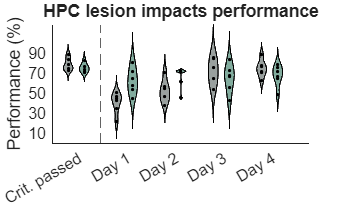

figure
hold on
title("HPC lesion impacts performance")
l_violin = [52 66 62]./255;
c_violin = [6 89 61]./255;
l_dot = [0 0 0]./255;
c_dot = [0 0 0]./255;
x_loc = [0 1 3 4 6 7 9 10 12 13];
for i =1:5
    Y(:,1) = Performance(i,lesion,1);
    Y(:,2) = Performance(i,ctrl,1);
    
    violin(Y, 'x', [x_loc(2*i-1) x_loc(2*i)], 'facecolor', [l_violin; c_violin], 'edgecolor', 'k', 'mc', [], 'medc', []);
    plot(repmat(x_loc(2*i-1), 6,1), Performance(i,lesion,1), 'o', 'MarkerEdgeColor', l_dot, 'MarkerFaceColor',l_dot, 'MarkerSize', 2)
    plot(repmat(x_loc(2*i), 6,1), Performance(i,ctrl,1), 'o', 'MarkerEdgeColor', c_dot, 'MarkerFaceColor',c_dot, 'MarkerSize', 2)
    clear Y
end

xticklabels({"Crit. passed", "Day 1", "Day 2", "Day 3" , "Day 4"})
xlim([-1 15])
ylim([0 120])
box off
xticks([0.5 3.5 6.5 9.5 12.5])
yticks(10:20:90)
ylabel("Performance (%)")
xline(2, '--')

Calculate error composition for the lesion and control group. Script can be found in GetTrialErrorsLesion.m script. Performance is recalculated and only testing trials are considered. Baseline is created on N=24 mice.

%%get baseline errors from behavior only
[~, N_mice_bl] = size(lesion_struct.events);
ErrorType_bl = nan(3, N_mice_bl+10);
N_error_bl = nan(N_mice_bl+10,1);

for m = 1:N_mice_bl
    disp(lesion_struct.details.Mouse(m))
    d = lesion_struct.details.LesionD1(m)-1;
    event = lesion_struct.events{d,m};
    [TrialStart, TrialStop, ZoneTriggered, context] = ParseTrials(event);
    [Correct, Incorrect, Timeout, port, time, TrainingTrials, all_outcome] = GetTrialOutcome(event,TrialStart,TrialStop,ZoneTriggered);
    TrialType  = ones(length(all_outcome),1);
    if ~isempty(TrainingTrials)
        TrialType([1; TrainingTrials(:,1)]) = 0; %1st trial is training when training trials are included in the session
    end
    %%get rewarded ports for this mouse
    reward_ports = unique(port);
    if length(reward_ports) > 2
        reward_ports(1) = [];
    end
    %only use testing trials
    [~,idx,~] = intersect(Incorrect(:,1),find(TrialType == 1));
    idx = sort(idx);
    if ~isempty(idx)
        Testing_Incorrect = Incorrect(idx,:);
        [ErrorType_bl(:,m), ~] =  GetWrongChoice(event, reward_ports, Testing_Incorrect);
        N_error_bl(m) = length(Testing_Incorrect(:,1));
    else
        ErrorType_bl(:,m) = [0 0 0];
    end
end

M94
M113
M118
M122
M151
M152
M154


Too short event flag in line 1212. Skipped for now but please fix it manually in the EventFile.


M155


Too short event flag in line 1396. Skipped for now but please fix it manually in the EventFile.
Too short event flag in line 1648. Skipped for now but please fix it manually in the EventFile.


M179
M180
M181


Too short event flag in line 427. Skipped for now but please fix it manually in the EventFile.


M182




%% now add the behavior mice too
for m = N_mice_bl+1:N_mice_bl+10
    disp(behavior_struct.details.Mouse(m-N_mice_bl))
    d = behavior_struct.details.DPassed(m-N_mice_bl);
    event = behavior_struct.D_events{d,m-N_mice_bl};
    [TrialStart, TrialStop, ZoneTriggered, context] = ParseTrials(event);
    [Correct, Incorrect, Timeout, port, time, TrainingTrials, all_outcome] = GetTrialOutcome(event,TrialStart,TrialStop,ZoneTriggered);
    TrialType  = ones(length(all_outcome),1);
    if ~isempty(TrainingTrials)
        TrialType([1; TrainingTrials(:,1)]) = 0; %1st trial is training when training trials are included in the session
    end
    %%get rewarded ports for this mouse
    reward_ports = unique(port);
    if length(reward_ports) > 2
        reward_ports(1) = [];
    end
    %only use testing trials
    [~,idx,~] = intersect(Incorrect(:,1),find(TrialType == 1));
    idx = sort(idx);
    if ~isempty(idx)
        Testing_Incorrect = Incorrect(idx,:);
        [ErrorType_bl(:,m), ~] =  GetWrongChoice(event, reward_ports, Testing_Incorrect);
        N_error_bl(m) = length(Testing_Incorrect(:,1));
    else
        ErrorType_bl(:,m) = [0 0 0];
    end
end

M95
M96
M97
M98
M99
M100
M114
M115
M116
M117



%get all days starting from day when passed
ctrl = find(lesion_struct.details.Group == "c");
lesion = find(lesion_struct.details.Group == "l");
starting_day = lesion_struct.details.LesionD1-1;

%% allocate variables for storing error information
[~, N_mice] = size(lesion_struct.events);
ErrorType = nan(5,3,N_mice); % percentage of error type; context error (1); port error(2); random(5)
N_error = nan(5,N_mice);

for m = 1:N_mice
    disp(lesion_struct.details.Mouse(m))
    for d = starting_day(m):starting_day(m)+4

        event = lesion_struct.events{d,m};
        [TrialStart, TrialStop, ZoneTriggered, context] = ParseTrials(event);
        [Correct, Incorrect, Timeout, port, time, TrainingTrials, all_outcome] = GetTrialOutcome(event,TrialStart,TrialStop,ZoneTriggered);
        TrialType  = ones(length(all_outcome),1);
        if ~isempty(TrainingTrials)
            TrialType([1; TrainingTrials(:,1)]) = 0; %1st trial is training when training trials are included in the session
        end
        %%get rewarded ports for this mouse
        reward_ports = unique(port);
        if length(reward_ports) > 2
            reward_ports(1) = [];
        end
        %only use testing trials
        [~,idx,~] = intersect(Incorrect(:,1),find(TrialType == 1));
        idx = sort(idx);
        if ~isempty(idx)
            Testing_Incorrect = Incorrect(idx,:);
            [ErrorType(d-starting_day(m)+1,:,m), ~] =  GetWrongChoice(event, reward_ports, Testing_Incorrect);
            N_error(d-starting_day(m)+1,m) = length(Testing_Incorrect(:,1));
        else
            ErrorType(d-starting_day(m)+1,:,m) = [0 0 0];
        end
    end
end

M94
M113
M118


Too short event flag in line 1466. Skipped for now but please fix it manually in the EventFile.
Too short event flag in line 708. Skipped for now but please fix it manually in the EventFile.


M122


Too short event flag in line 991. Skipped for now but please fix it manually in the EventFile.


M151
M152
M154


Too short event flag in line 1212. Skipped for now but please fix it manually in the EventFile.


M155


Too short event flag in line 1396. Skipped for now but please fix it manually in the EventFile.
Too short event flag in line 1648. Skipped for now but please fix it manually in the EventFile.


M179
M180


Too short event flag in line 744. Skipped for now but please fix it manually in the EventFile.
Too short event flag in line 3847. Skipped for now but please fix it manually in the EventFile.
Too short event flag in line 4468. Skipped for now but please fix it manually in the EventFile.
Too short event flag in line 3394. Skipped for now but please fix it manually in the EventFile.
Too short event flag in line 3990. Skipped for now but please fix it manually in the EventFile.


M181


Too short event flag in line 427. Skipped for now but please fix it manually in the EventFile.
Too short event flag in line 414. Skipped for now but please fix it manually in the EventFile.
Too short event flag in line 1618. Skipped for now but please fix it manually in the EventFile.


M182


Too short event flag in line 377. Skipped for now but please fix it manually in the EventFile.



%% take the mean for control and lesion
ctrl_error = mean(ErrorType(:,:,ctrl), 3 );
lesion_error = mean(ErrorType(:,:,lesion),3);

%% get baseline with all the mice (N = 24)
baseline = mean([ErrorType_bl reshape(ErrorType(1,:,:),3,12)],2);


%% run chi square on data
p  = nan(4,2);
X2 = nan(4,2);

for i = 1:4
    x = [baseline lesion_error(i+1,:)'];
    [~,p(i,1),X2(i,1)] = chi2cont(x);
    x = [baseline ctrl_error(i+1,:)'];
    [~,p(i,2),X2(i,2)] = chi2cont(x);
end

%get average error
avg_error_bl = mean([N_error_bl; N_error(1,:)']);

avg_error = nan(4,2);
for i =1:4
    avg_error(i,1) = mean(N_error(i+1,lesion));
    avg_error(i,2)= mean(N_error(i+1,ctrl));
end
p

p =     0.0000    0.0994
    0.0009    0.6070
    0.0001    0.0140
    0.0030    0.1895


## Extended Data Fig. 1h

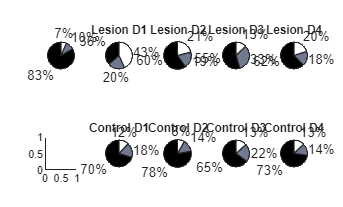

figure
tiledlayout(2,5)
nexttile;
title("Baseline")
pie(baseline)

for i = 1:4
    nexttile;
    pie(lesion_error(i+1,:))
    box off 
    axis off
    axis square
    title(strcat("Lesion D", num2str(i)))

end

nexttile;
axis square

for i = 1:4
    nexttile;
    pie(ctrl_error(i+1,:))
    box off 
    axis off
    axis square
    title(strcat("Control D", num2str(i)))
end
colormap bone

Finally read excel sheet for lesion scoring. CA1/CA3/DG area were scored by MI and GT, volume was calculated by interpolating between measurment points (every 150 um). Script can be found in GetHPCVolume.m.

tbl = readtable(strcat(main_path, "\Discrimination 2025 data\Behavior\AreaSummary.xlsx"));

%% calculate volume from distance and summed area
for i = 1:length(tbl.distance_um_)
    tbl.CA1Volume(i) = (tbl.CA1Area_um2_(i)*tbl.distance_um_(i))/1e9; % in mm3
    tbl.CA3Volume(i) = (tbl.CA3Area(i)*tbl.distance_um_(i))/1e9; % in mm3
    tbl.DGVolume(i) = (tbl.DGArea(i)*tbl.distance_um_(i))/1e9;
end

%% compare ctrl vs lesion volume
ctrl = find(tbl.type == 0);
lesion = find(tbl.type == 1);
left = find(tbl.hemisphere == 1);
right = find(tbl.hemisphere == 2);

meanCA1 = [mean(tbl.CA1Volume(ctrl)) mean(tbl.CA1Volume(lesion))];
meanCA3 = [mean(tbl.CA3Volume(ctrl)) mean(tbl.CA3Volume(lesion))];
meanDG = [mean(tbl.DGVolume(ctrl)) mean(tbl.DGVolume(lesion))];

semCA1 = [std(tbl.CA1Volume(ctrl))/sqrt(10) std(tbl.CA1Volume(lesion))/sqrt(12)];
semCA3 = [std(tbl.CA3Volume(ctrl))/sqrt(10) std(tbl.CA3Volume(lesion))/sqrt(12)];
semDG = [std(tbl.DGVolume(ctrl))/sqrt(10) std(tbl.DGVolume(lesion))/sqrt(12)];

%% calculate the % volume compared to the mean of the control volume
tbl.CA1Relative =tbl.CA1Volume./meanCA1(1)*100;
tbl.CA3Relative =tbl.CA3Volume./meanCA3(1)*100;
tbl.DGRelative =tbl.DGVolume./meanDG(1)*100;

%% now take the average of left and right
lesion_left = intersect(lesion,left);
lesion_right = intersect(lesion,right);

%% calculate the mean relative volume (left & right)
relative_CA1 = (tbl.CA1Relative(lesion_left)+tbl.CA1Relative(lesion_right))/2;
relative_CA3 = (tbl.CA3Relative(lesion_left)+tbl.CA3Relative(lesion_right))/2;
relative_DG = (tbl.DGRelative(lesion_left)+tbl.DGRelative(lesion_right))/2;

## Extended Data Fig. 1g

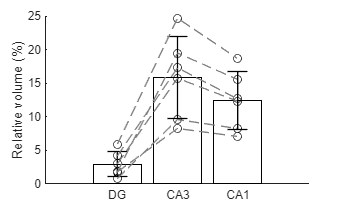

figure
hold on
bar(0, mean(relative_DG), 'FaceColor','w', 'EdgeColor', 'k')
bar(1, mean(relative_CA3), 'FaceColor','w', 'EdgeColor', 'k')
bar(2, mean(relative_CA1), 'FaceColor','w', 'EdgeColor', 'k')
xticks([0 1 2])
xticklabels({'DG', 'CA3', 'CA1'})
ylabel("Relative volume (%)")

er = errorbar([0 1 2], [mean(relative_DG) mean(relative_CA3) mean(relative_CA1)], [std(relative_DG) std(relative_CA3) std(relative_CA1)]);
er.Color=  [0 0 0];
er.LineStyle  = 'none';
er.LineWidth = 1;
er.CapSize  =15;

plot(zeros(6,1), relative_DG, 'ko')
plot(ones(6,1), relative_CA3, 'ko')
plot(repmat(2,6,1), relative_CA1, 'ko')
plot([0 1 2 ], [relative_DG relative_CA3 relative_CA1], '--', 'Color', [.5 .5 .5])

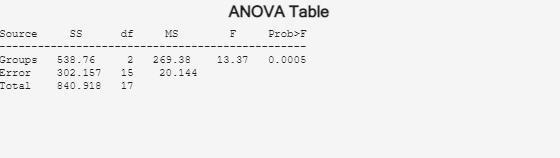

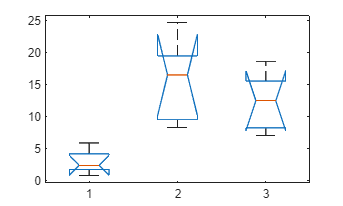


%% do statisics - one-way anova with post-hoc tukey's tets
anova_data = [relative_DG; relative_CA3; relative_CA1];
anova_label = [repmat(1, 6,1); repmat(2, 6,1); repmat(3, 6,1)];


%% NOTE. anova1 runs really slow on MATLAB 2025a.

[p,tbl,stats] = anova1(anova_data,anova_label);

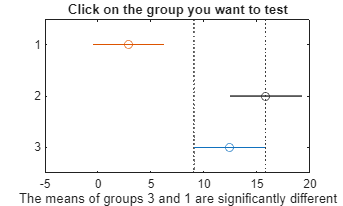

c =     1.0000    2.0000  -19.6646  -12.9339   -6.2032    0.0004
    1.0000    3.0000  -16.2350   -9.5043   -2.7736    0.0061
    2.0000    3.0000   -3.3011    3.4296   10.1603    0.4044


c= multcompare(stats)